# Create Deep Learning Network Architecture

Script for creating the layers for a deep learning network with:

Run the script to create the layers in the workspace variable `layers`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 23-Dec-2019 18:43:20

## Create the Array of Layers

layers = [
    imageInputLayer([32 32 1],"Name","data")
    maxPooling2dLayer([2 2],"Name","maxpool_1","Stride",[2 2])
    convolution2dLayer([3 3],32,"Name","conv1","Stride",[2 2])
    reluLayer("Name","relu_1")
    maxPooling2dLayer([2 2],"Name","maxpool_2","Stride",[2 2])
    convolution2dLayer([3 3],64,"Name","conv","Stride",[2 2])
    reluLayer("Name","relu_2")
    fullyConnectedLayer(1024,"Name","fc1")
    fullyConnectedLayer(50,"Name","fc2")
    dropoutLayer(0.4,"Name","dropout40%")
    fullyConnectedLayer(40,"Name","fc3")
    fullyConnectedLayer(5,"Name","fc4")
    fullyConnectedLayer(1,"Name","fc5")
    softmaxLayer("Name","softmax")
    classificationLayer("Name","output")];

## Plot the Layers

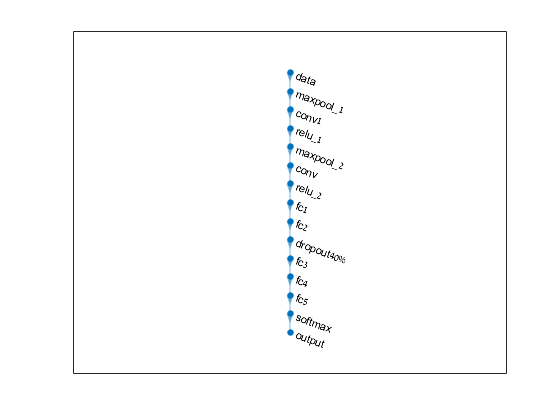

plot(layerGraph(layers));